Funcions usades en els exercicis del curs OR

E1. NLO program

syms x
f(x)=x^4-16*x^3+45*x^2-20*x+203

$$f(x) = x^{4}-16\,x^{3}+45\,x^{2}-20\,x+203$$

fprime=diff(f)

$$fprime(x) = 4\,x^{3}-48\,x^{2}+90\,x-20$$

opts=double(solve(fprime==0,x))

opts =     2.0000
    0.2566
    9.7434


opts(1)

ans = 2

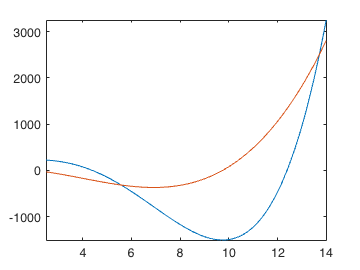

fplot(f),hold on
xlim([opts(1)+0.5,opts(3)+2])
xlim([2.5,14])
fplot(fprime),hold off

syms x
f(x)=(x-1)*(x+2)*(x-6)*(x+3)*x

$$f(x) = x\,\left(x-1\right)\,\left(x+2\right)\,\left(x+3\right)\,\left(x-6\right)$$

expand(f)

$$ans(x) = x^{5}-2\,x^{4}-23\,x^{3}-12\,x^{2}+36\,x$$

fprime=diff(f)

$$fprime(x) = x\,\left(x-1\right)\,\left(x+2\right)\,\left(x+3\right)+x\,\left(x-1\right)\,\left(x+2\right)\,\left(x-6\right)+x\,\left(x-1\right)\,\left(x+3\right)\,\left(x-6\right)+x\,\left(x+2\right)\,\left(x+3\right)\,\left(x-6\right)+\left(x-1\right)\,\left(x+2\right)\,\left(x+3\right)\,\left(x-6\right)$$

opts=sort(double(solve(fprime==0,x)))

opts =    -2.5941
   -1.0565
    0.5601
    4.6905


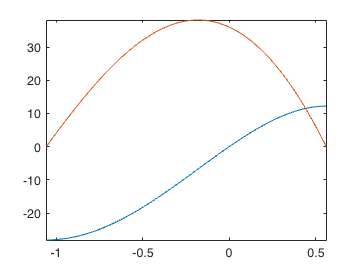

fplot(f),hold on
xlim([opts(2),opts(3)])
%xlim([2.5,14])
fplot(fprime),hold off

% Compute simplified symbolic expression
simplifiedExpr = expand(ans)

$$simplifiedExpr(x) = x^{5}-2\,x^{4}-23\,x^{3}-12\,x^{2}+36\,x$$

Exercici Hessià

cd '~/GitHub/OperationalResearch/matlab/'
syms x y
f(x,y)=x^3+2*y^3-x*y 

$$f(x, y) = x^{3}-x\,y+2\,y^{3}$$

fsurf(f)
h=hessian(f)

$$h(x, y) = \left(\begin{array}{cc} 6\,x & -1\\ -1 & 12\,y \end{array}\right)$$

eval=eig(h)

$$eval(x, y) = \left(\begin{array}{c} 3\,x+6\,y+\sqrt{9\,x^{2}-36\,x\,y+36\,y^{2}+1}\\ 3\,x+6\,y-\sqrt{9\,x^{2}-36\,x\,y+36\,y^{2}+1} \end{array}\right)$$

eval(0,0)

$$ans = \left(\begin{array}{c} 1\\ -1 \end{array}\right)$$

h(3,3)

$$ans = \left(\begin{array}{cc} 18 & -1\\ -1 & 36 \end{array}\right)$$

eval(3,3)

$$ans = \left(\begin{array}{c} \sqrt{82}+27\\ 27-\sqrt{82} \end{array}\right)$$

eval(-3,-3)

$$ans = \left(\begin{array}{c} \sqrt{82}-27\\ -\sqrt{82}-27 \end{array}\right)$$

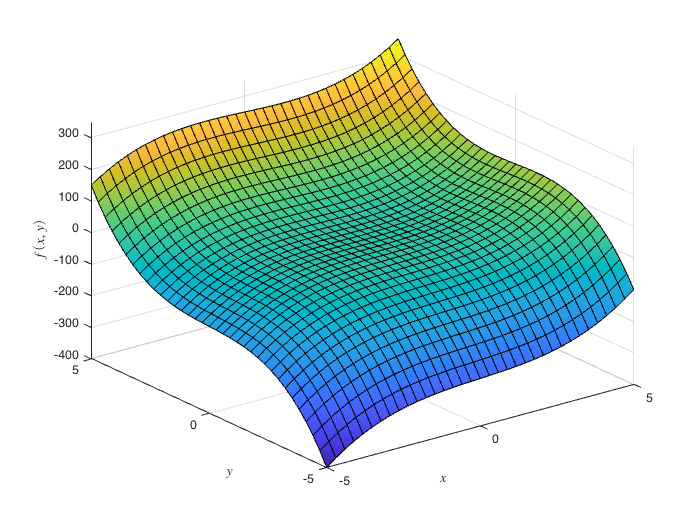

xlabel('$x$','interpreter','latex')
ylabel('$y$','interpreter','latex')
zlabel('$f(x,y)$','interpreter','latex')
saveas(gcf,'../figures/x3plus2y3minusxy.png')

Constrained optimization

syms x y
f(x,y)=x^2-y

$$f(x, y) = x^{2}-y$$

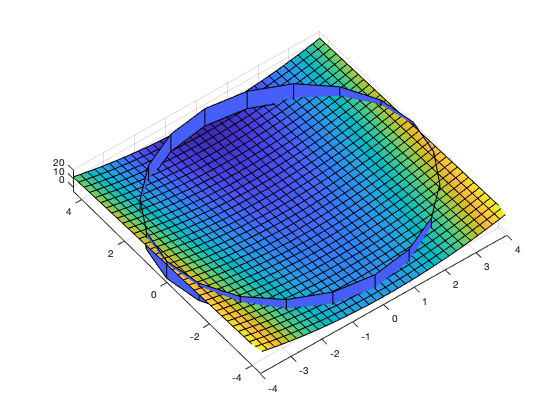

r = 4;
[X,Y,Z] = cylinder(r);
h = 20;
Z = Z*h;
surf(X,Y,Z),hold on
fsurf(f),hold off

xlim([-4.00 4.00])
ylim([-4.4 4.4])
zlim([-5.0 20.0])
view([-37.2 84.6])
saveas(gcf,'../figures/Lagrangex2minusy.png')

syms l b h lambda
h=3

h = 3

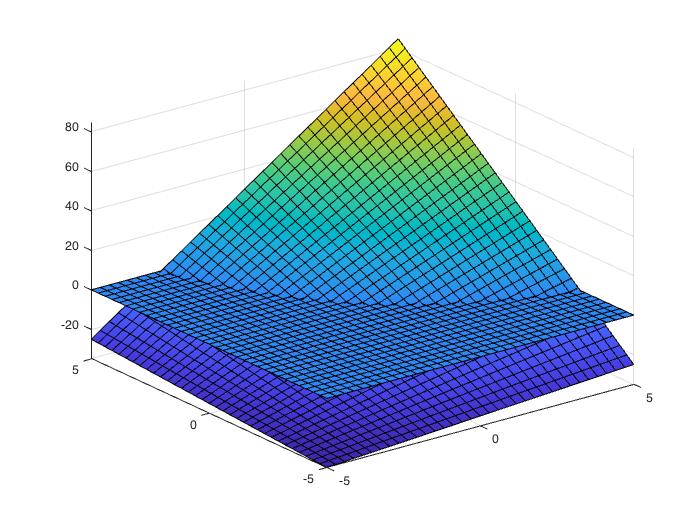

A = l * b + 2 * b * h + 2 * l * h; % area of needed sheet metal (thickness = 1, because we are lazy guys)
V = l * b * h - 10 == 0; % volume constraint 10 m³
fsurf(A),hold on
fsurf(V),hold off


L = A + lambda * lhs(V); % Langrange function
dL_dl = diff(L,l) == 0; % derivative of L with respect to l
dL_db = diff(L,b) == 0; % derivative of L with respect to b
dL_dh = diff(L,h) == 0; % derivative of L with respect to h
dL_dlambda = diff(L,lambda) == 0; % derivative of L with respect to lambda
system = [dL_dl; dL_db; dL_dh; dL_dlambda]; % build the system of equations
[l_val, b_val, h_val,lambda_val] = solve(system, [l b h lambda], 'Real', true) % solve the system of equations and display the results 

Error using sym.getEqnsVars>checkVariables (line 98)
Second argument must be a vector of symbolic variables.

Error in sym.getEqnsVars (line 62)
    checkVariables(vars);

Error in 

results_numeric = double([l_val, b_val, h_val,lambda_val]) % show results in a vector of data type double
V_res = l_val * b_val * h_val % calculate the resulting volume (should be 10, if correct)
A_res = l_val * b_val + 2 * b_val * h_val + 2 * l_val * h_val % calculate the needed amount (area) of sheet metal

divertimento

syms x k
F3 = symsum(x^k/factorial(k),k,1,Inf)

$$F3 = {\mathrm{e}}^{x}-1$$

F4 = symsum(1/(k^3*(sin(k))^2),k,1,100)

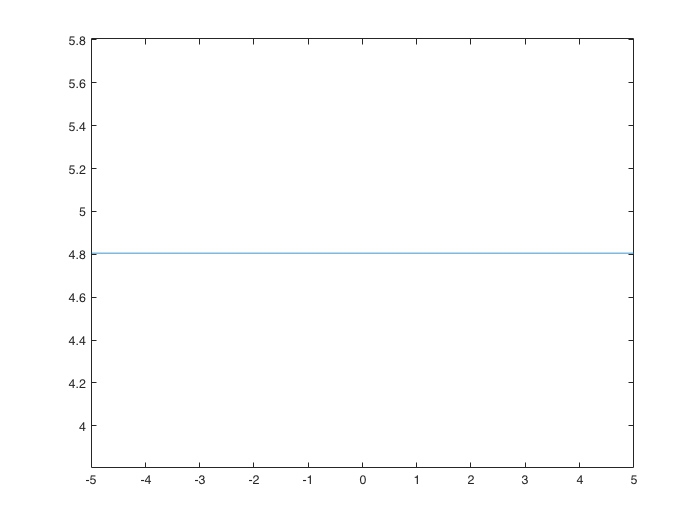

fplot(F4)